% Jep Brinkmann Thesis HMM example
clc; close all;
k = 4;
d = 30;
n = 5;
% m = 1e5;

hmm_options.epsilon = 1/7;
hmm_options.method = "random";
hmm_options.distribution = 'Normal';

ps = 20;
sampleArray = ceil(logspace(3, 7, ps));

BWmax = 10;
Nruns = 20;

BWCost = zeros(BWmax, Nruns);
BWTime = zeros(BWmax, Nruns);

UncoupledCost = zeros(ps, Nruns);
UncoupledTime = zeros(ps, Nruns);

CoupledCost = zeros(ps, Nruns);
CoupledTime = zeros(ps, Nruns);

JPTTime = zeros(ps, Nruns);

% save("PerformanceTests/Time_Performance_Costs", "BWCost", "UncoupledCost", "CoupledCost", "TensorCost")

cpd_options.maxIter = 2500;
cpd_options.tol = 1e-14;
cpd_options.th_relerr = 1e-7;
cpd_options.epsilon = 1/10;

alpha = 0.1;
rho = 0.85;

T_hats = cell(n,1);
O_hats = cell(n,1);

P3 = cell(n,1);
Dspace = zeros(n,d);


for j = 1:Nruns
    for i = progress(1:ps)
        % [T, O, pi, k, d] = generateHMM(k, d, n, cpd_options);

        [T, Os, pi, ~, ~] = generateContinuousHMM(k, d, n, hmm_options);

        tic
        % [seq, ~] = generate_multivariate_hmm_sequence(T, O, pi, sampleArray(i));
        seq = generate_continuous_multivariate_hmm_sequence(T, Os, pi, sampleArray(i), 0);

        [~, mins, maxs] = NormalizeData(seq);
        [T, O_hists] = Discretize_cHMM(T, Os, mins, maxs, d);

        for ii = 1:n
            P3{ii} = ProbabilityTensorGenerate(seq(ii, :), 3, d);
            Dspace(ii, :) = linspace(min(seq(ii, :)), max(seq(ii, :)), d);
        end
        JPTTime(i, j) = toc;

        % Baum-Welch
        
        if(i <= BWmax)
            tic;
            [Mu,Cov,A,Pi]=BaumWelch(seq',k);

            T_hat = Stochasticize(A);
            [T_hat, O_hats] = Discretize_cHMM_BW(T_hat, Mu, Cov, mins, maxs, d);
            
            Pbest = MultivariatePermutationFitEmission(O_hists, O_hats);
            T_hat = Pbest * T_hat * Pbest';
            for ii = 1:n
                O_hats{ii} = O_hats{ii} * Pbest';
            end

            BWCost(i, j) = HMMError(T, O_hists, T_hat, O_hats, false);  
            BWTime(i, j) = toc;
        end

        % Uncoupled CPD
        tic
        T_hat = zeros(k,k);
        for ii = 1:n
            [A, B, C, ~, ~] = cpd_als_3d(P3{ii}, k, cpd_options);
            O_hat = Stochasticize(B);
            T_hats{ii} = Stochasticize(pinv(Stochasticize(B)) * Stochasticize(C));
        
            Pbest = PermutationFit(T, T_hats{ii}, true);
            T_hats{ii} = Pbest * T_hats{ii} * Pbest';
            T_hat = T_hat + (1/n) * T_hats{ii};
        
            O_hats{ii} = O_hat * Pbest';
        end
    
        UncoupledCost(i, j) = HMMError(T, O_hists, T_hat, O_hats, false);  
        UncoupledTime(i, j) = toc;
        
        % Coupled CPD
        tic
        [T_hat, O_hats, ~, ~] = multivariate_coupled_cpd_2(P3, k, d, n, alpha, rho, cpd_options);
        pi_hat = findStationaryDistribution(T_hat')';
        [T_hat, O_hats, ~] = remove_hmm_permutation_transition(T, T_hat, O_hats, pi_hat);
    
        CoupledCost(i, j) = HMMError(T, O_hists, T_hat, O_hats, false);  
        CoupledTime(i, j) = toc;
    end
end

Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]

Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]


save("PerformanceTests/Time_Performance_Costs2", "BWCost", "BWTime", "UncoupledCost", "UncoupledTime", "CoupledCost", "CoupledTime", "JPTTime", "BWmax", "sampleArray");


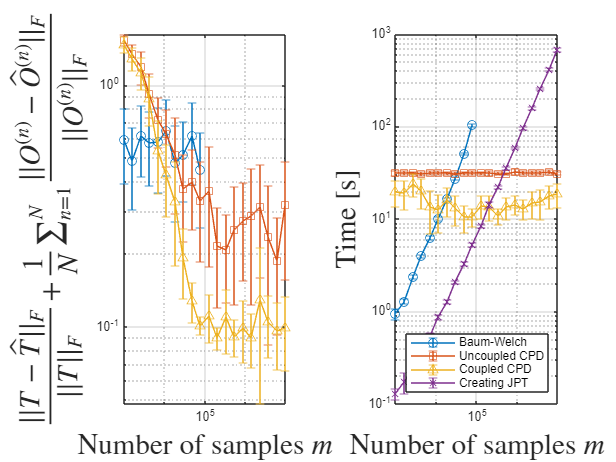

load("PerformanceTests/Time_Performance_Costs2");



[BWCostSTD, BWCostMean] = std(BWCost, 0, 2);
[UncoupledCostSTD, UncoupledCostMean] = std(UncoupledCost, 0, 2);
[CoupledCostSTD, CoupledCostMean] = std(CoupledCost, 0, 2);

[BWTimeSTD, BWTimeMean] = std(BWTime, 0, 2);
[UncoupledTimeSTD, UncoupledTimeMean] = std(UncoupledTime, 0, 2);
[CoupledTimeSTD, CoupledTimeMean] = std(CoupledTime, 0, 2);
[JPTTimeSTD, JPTTimeMean] = std(JPTTime, 0, 2);

figure()
subplot(1, 2, 1)

errorbar(sampleArray(1:BWmax)', BWCostMean, BWCostSTD/2, "-o"); hold on;
errorbar(sampleArray', UncoupledCostMean, UncoupledCostSTD/2, "-s"); hold on;
errorbar(sampleArray', CoupledCostMean, CoupledCostSTD/2, "-^");
set(gca,'YScale','log', 'XScale', 'log');
grid on;
% title("HMM error over samples",'FontSize',24,'FontWeight','bold')
ylabel("$\frac{||T - \hat{T}||_F}{||T||_F} + \frac{1}{N} \sum_{n=1}^N \frac{||O^{(n)} - \hat{O}^{(n)}||_F}{||O^{(n)}||_F}$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
xlabel("Number of samples $m$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
hold off;

subplot(1, 2, 2)
errorbar(sampleArray(1:BWmax)', BWTimeMean, BWTimeSTD/2, "-o"); hold on;
errorbar(sampleArray', UncoupledTimeMean, UncoupledTimeSTD/2, "-s"); hold on;
errorbar(sampleArray', CoupledTimeMean, CoupledTimeSTD/2, "-^"); hold on;
errorbar(sampleArray', JPTTimeMean, JPTTimeSTD/2, "-x");

set(gca,'YScale','log', 'XScale', 'log');
grid on; legend("Baum-Welch", "Uncoupled CPD", "Coupled CPD", "Creating JPT", Location="southeast")
% title("Calculation time over samples",'FontSize',24,'FontWeight','bold')
ylabel("Time [s]", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
xlabel("Number of samples $m$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')

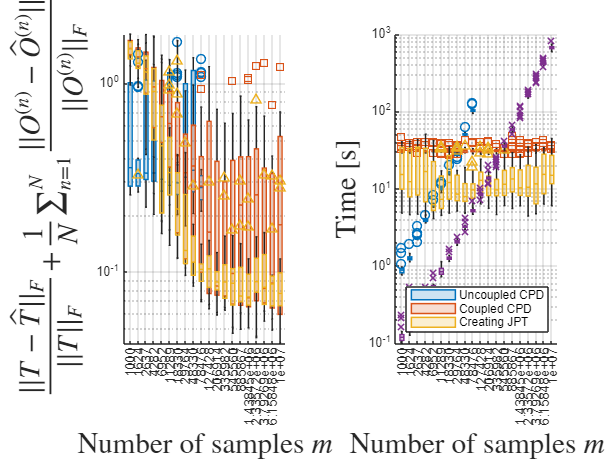


figure()
subplot(1, 2, 1)
cmap = orderedcolors("gem");

boxchart(BWCost', "MarkerStyle", 'o'); hold on;
boxchart(UncoupledCost', "MarkerStyle", 's'); hold on;
boxchart(CoupledCost', "MarkerStyle", '^'); hold on;

xticklabels(sampleArray);

set(gca,'YScale','log');

grid on;
% title("HMM error over samples",'FontSize',24,'FontWeight','bold')
ylabel("$\frac{||T - \hat{T}||_F}{||T||_F} + \frac{1}{N} \sum_{n=1}^N \frac{||O^{(n)} - \hat{O}^{(n)}||_F}{||O^{(n)}||_F}$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
xlabel("Number of samples $m$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
hold off;

subplot(1, 2, 2)

boxchart(BWTime', "MarkerStyle", 'o'); hold on;
boxchart(UncoupledTime', "MarkerStyle", 's'); hold on;
boxchart(CoupledTime', "MarkerStyle", '^'); hold on;
boxchart(JPTTime', "MarkerStyle", 'x'); hold on;
xticklabels(sampleArray);

set(gca,'YScale','log');
grid on; 
legend("Uncoupled CPD", "Coupled CPD", "Creating JPT", Location="southeast");
% title("Calculation time over samples",'FontSize',24,'FontWeight','bold')
ylabel("Time [s]", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
xlabel("Number of samples $m$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')